close all;
clear all;
clc;
recorder=audiorecorder(16000,8,2);
disp("speak your name");

speak your name


drawnow();
recordblocking(recorder,3);
data=getaudiodata(recorder);
f=VoiceFeature(data);

fea = 2336

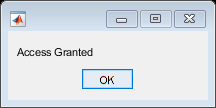

load database.mat;
D=[];
for(i=1:size(Feature,1))
    d=sum(abs(Feature(i)-f));
    D=[D d];
end
sm=inf;
ind=-1;
for(i=1:length(D))
    if(D(i)<sm)
        sm=D(i);
        ind=i;
    end
end
detected_id=UserId(ind);
cam=webcam();
preview(cam);
pause(2);
img=snapshot(cam);
pause(2);
closePreview(cam);
f1=Face_Features(img);
load dbase.mat;


m=find(detected_id==uid,1);
dis1=mean(feature1(m));
dis2=mean(f1(m));
dist=abs(dis1-dis2);
dis3=min(dist);
if(dist<10)
    msgbox('Access Granted');

else 
    msgbox('Access Denied');
end